## **Esercizio 3**

clear variables; close all; clc;

### **Il modello di una macchina per la produzione della carta è il seguente:**

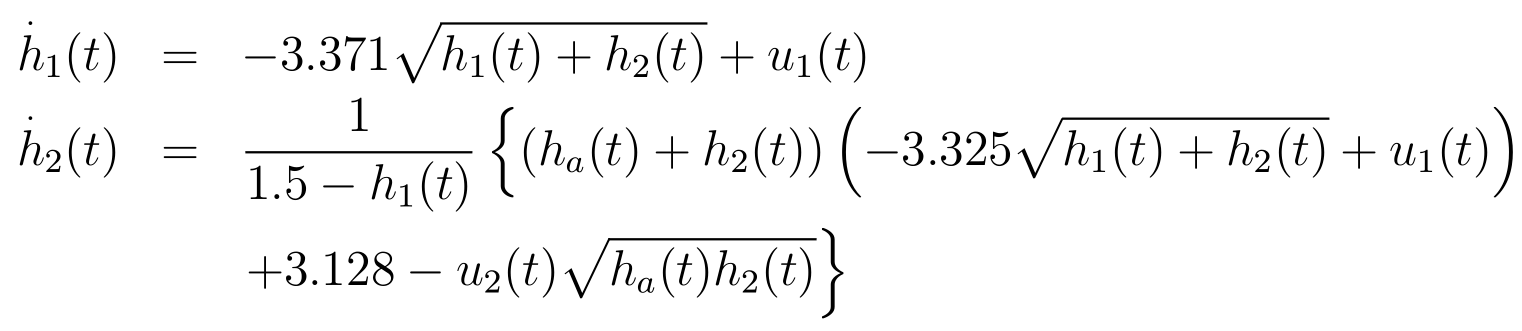

h_1 = 0.7;
h_2 = 1.5;

% disturbo di equilibrio: altezza [m]
h_a = 10.32;

u_1 = 3.371*sqrt(h_1+h_2)

u_1 = 5.0000

u_2 = (((h_a+h_2) * (-3.325*sqrt(h_1+h_2)+u_1)) + 3.128) / sqrt(h_a*h_2)

u_2 = 1.0000

### 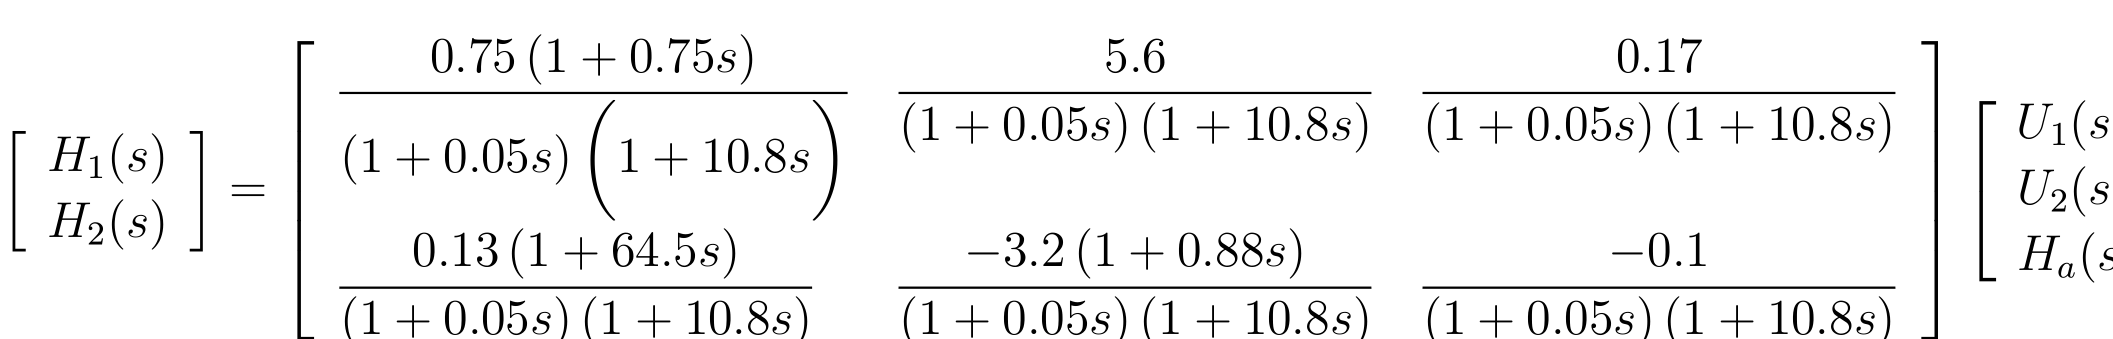

### **2) Matrice dei guadagni relativi**

**Si determini la matrice dei guadagni relativi tre le variabili di controllo e quelle controllate e si individuino i migliori accoppiamenti ingresso/uscita.**

s = tf('s');
G11 = 0.75 * (1+0.75*s) / ((1+0.05*s) * (1+10.8*s));
G12 = 5.6 / ((1+0.05*s) * (1+10.8*s));
G21 = 0.13 * (1+64.5*s) / ((1+0.05*s) * (1+10.8*s));
G22 = -3.2 * (1+0.88*s) / ((1+0.05*s) * (1+10.8*s));
G = [G11 G12; G21 G22]


G =
 
  From input 1 to output...
          0.5625 s + 0.75
   1:  ----------------------
       0.54 s^2 + 10.85 s + 1
 
           8.385 s + 0.13
   2:  ----------------------
       0.54 s^2 + 10.85 s + 1
 
  From input 2 to output...
                5.6
   1:  ----------------------
       0.54 s^2 + 10.85 s + 1
 
           -2.816 s - 3.2
   2:  ----------------------
       0.54 s^2 + 10.85 s + 1
 
Continuous-time transfer function.



G_0 = dcgain(G)

G_0 =     0.7500    5.6000
    0.1300   -3.2000


G_dcgain_rel = G_0 .* ((inv(G_0))')

G_dcgain_rel =     0.7673    0.2327
    0.2327    0.7673


### **3) Progettazione regolatore di disaccopiamento**

**Si progetti un regolatore di disaccoppiamento e se ne disegni lo schema realizzativo.**

D11 = 1;
D22 = 1;
D12 = minreal(-G12/G11);
D21 = minreal(-G21/G22);
D = [D11 D12; D21 D22]


D =
 
  From input 1 to output...
   1:  1
 
       2.978 s + 0.04616
   2:  -----------------
           s + 1.136
 
  From input 2 to output...
        -9.956
   1:  ---------
       s + 1.333
 
   2:  1
 
Continuous-time transfer function.



Gt = minreal(G*D, 1e-5)


Gt =
 
  From input 1 to output...
          1.042 s^2 + 33.45 s + 2.057
   1:  ---------------------------------
       s^3 + 21.23 s^2 + 24.68 s + 2.104
 
                9.747e-14 s^2 + 1.218e-14 s + 9.518e-17
   2:  ---------------------------------------------------------
       s^5 + 41.32 s^4 + 453.1 s^3 + 537.4 s^2 + 87.99 s + 3.897
 
  From input 2 to output...
                      -9.747e-14 s - 9.138e-15
   1:  -------------------------------------------------------
       s^5 + 41.52 s^4 + 461 s^3 + 617.6 s^2 + 102.7 s + 4.572
 
          -5.215 s^2 - 167.5 s - 10.3
   2:  ---------------------------------
       s^3 + 21.43 s^2 + 28.64 s + 2.469
 
Continuous-time transfer function.



### **4) Progettazione regolatori PI**

**Si progettino due regolatori disaccoppiati di tipo PI in modo da garantire, per i singoli anelli:**

- **Margine di fase di almeno 60°**

- **Tempo di assestamento della risposta allo scalino di circa 10 unità di tempo.**

### **Analisi G11:**

G1t_mu = dcgain(Gt(1,1))

G1t_mu = 0.9775

G1t_tau = -1./zero(Gt(1,1))

G1t_tau =     0.0312
   16.2309


G1t_T = -1./pole(Gt(1,1))

G1t_T =     0.0500
    0.8800
   10.8000


G1t = G1t_mu * (1+G1t_tau(1)*s) * (1+G1t_tau(2)*s) / ((1+G1t_T(1)*s) * (1+G1t_T(2)*s) * (1+G1t_T(3)*s));

#### **Approsimazione G11 (model reduction):**

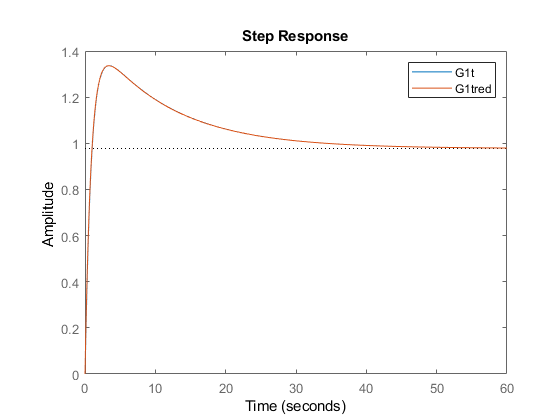

% approssimazione poli dominanti
% cancellazione zero/pole matching
% G1tred = balred(Gt(1,1), 2);
G1tred = G1t_mu * (1+G1t_tau(2)*s) / ((1+G1t_T(2)*s) * (1+G1t_T(3)*s));

figure; hold on; legend;
step(G1t);
step(G1tred);

S1 = stepinfo(G1t, 'SettlingTimeThreshold', 0.005);
S1 = S1.SettlingTime

S1 = 50.7344

S1t = stepinfo(G1tred, 'SettlingTimeThreshold', 0.005);
S1t = S1t.SettlingTime

S1t = 50.7155

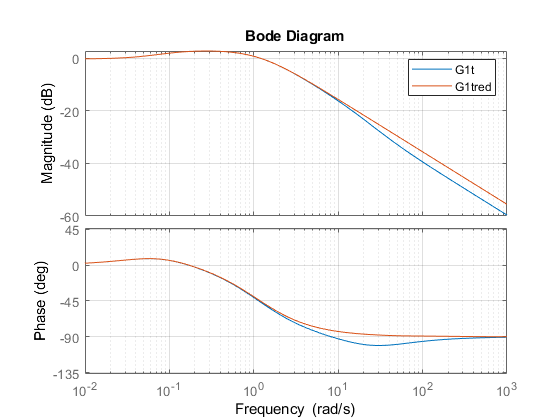

figure; hold on; legend; bode(G1t); bode(G1tred); grid on;

#### **Progettazione R1:**

w = 0.46;
% L1_tau è il polo NON cancellato dal regolatore R1
L1_tau = 10.8; 
R1_mu = w/G1t_mu * sqrt((1+(L1_tau^2)*(w^2))/(1+(16.2^2)*(w^2)))

R1_mu = 0.3172

L1 = minreal(R1_mu*G1t_mu/s * (1+16.2*s)/(1+L1_tau*s));
F1 = minreal(L1/(1+L1));
zpk(F1)


ans =
 
   0.46506 (s+0.06173)
  ----------------------
  (s+0.5003) (s+0.05738)
 
Continuous-time zero/pole/gain model.



#### **Approsimazione F1 (model reduction):**

F1_tau = -1./zero(F1)

F1_tau = 16.2000

F1_T = -1./pole(F1)

F1_T =     1.9989
   17.4265


dcgain(F1)

ans = 1.0000

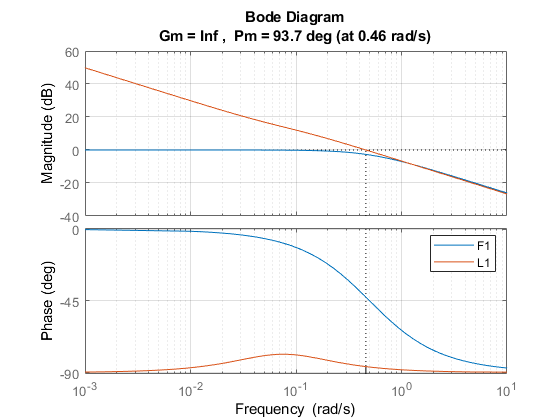

F1 = 1/(1+F1_T(1)*s);
% F1 = balred(F1, 1);
figure; hold on; margin(F1); margin(L1); grid on; legend;

F1t = stepinfo(F1, 'SettlingTimeThreshold', 0.01);
F1t = F1t.SettlingTime

F1t = 9.2054

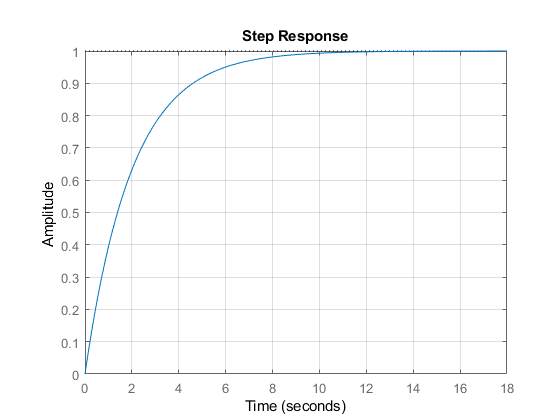

figure; step(F1); grid minor;

### **Analisi G22:**

% G2t = G22 - G21 * G12 / G11;
G2t_mu = dcgain(Gt(2,2))

G2t_mu = -4.1707

G2t_tau = -1./zero(Gt(2,2))

G2t_tau =     0.0312
   16.2309


G2t_T = -1./pole(Gt(2,2))

G2t_T =     0.0500
    0.7500
   10.8000


G2t = G2t_mu * (1+G2t_tau(1)*s) * (1+G2t_tau(2)*s) / ((1+G2t_T(1)*s) * (1+G2t_T(2)*s) * (1+G2t_T(3)*s));

### **Approsimazione G22:**

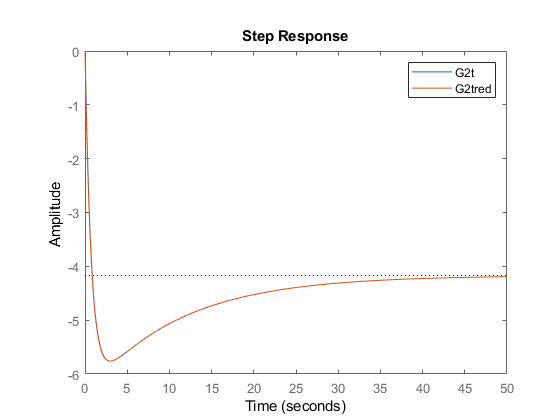

% approssimazione poli dominanti
% cancellazione zero/pole matching
% G1tred = balred(Gt(2,2), 2);
G2tred = G2t_mu * (1+G2t_tau(2)*s) / ((1+G2t_T(2)*s) * (1+G2t_T(3)*s));

figure; hold on; legend; step(G2t); step(G2tred);

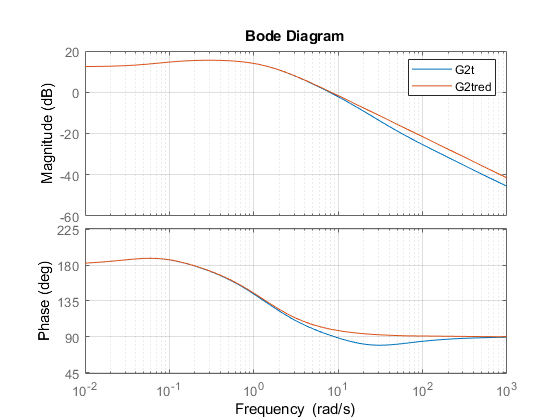

figure; hold on; legend; bode(G2t); bode(G2tred); grid on;

#### **Progettazione R2:**

L2_tau = 10.8;
mu2 = w/G2t_mu * sqrt((1+(L2_tau^2)*(w^2))/(1+(16.2^2)*(w^2)))

mu2 = -0.0743

L2 = minreal(G2t_mu*mu2/s * (1+16.2*s)/(1+L2_tau*s));
F2 = minreal(L2/(1+L2));
zpk(F2)


ans =
 
   0.46506 (s+0.06173)
  ----------------------
  (s+0.5003) (s+0.05738)
 
Continuous-time zero/pole/gain model.



#### **Approsimazione F2 (model reduction):**

F2_tau = -1./zero(F2)

F2_tau = 16.2000

F2_T = -1./pole(F2)

F2_T =     1.9989
   17.4265


dcgain(F2)

ans = 1.0000

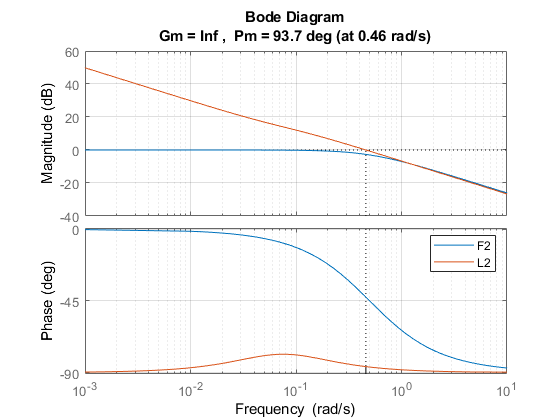

F2 = 1/(1+F2_T(1)*s);
% F2 = balred(F2, 1);

figure; hold on; bode(F2); margin(L2); grid on; legend;

F2t = stepinfo(F2, 'SettlingTimeThreshold', 0.01);
F2t = F2t.SettlingTime

F2t = 9.2054

figure; step(F2); grid minor;

### **5) Progettazione compensatore del disturbo in anello aperto**

**Sul sistema disaccoppiato e regolato con i PI, si progetti anche un regolatore in anello aperto in grado di eliminare, o ridurre, l’effetto del disturbo h_a e si disegni lo schema di controllo complessivo.**

% M(s) = - H(s) * G(s)^-1
M1 = -0.17/G1t_mu * (1+G1t_T(2)*s) / ((1+G1t_tau(1)*s)*(1+G1t_tau(2)*s))


M1 =
 
     -0.153 s - 0.1739
  ------------------------
  0.5064 s^2 + 16.26 s + 1
 
Continuous-time transfer function.



dcgain(M1)

ans = -0.1739

-1./zero(M1)

ans = 0.8800

-1./pole(M1)

ans =     0.0312
   16.2309


M2 = 0.1/G2t_mu * (1+G2t_T(2)*s) / ((1+G2t_tau(1)*s)*(1+G2t_tau(2)*s))


M2 =
 
    -0.01798 s - 0.02398
  ------------------------
  0.5064 s^2 + 16.26 s + 1
 
Continuous-time transfer function.



dcgain(M2)

ans = -0.0240

-1./zero(M2)

ans = 0.7500

-1./pole(M2)

ans =     0.0312
   16.2309